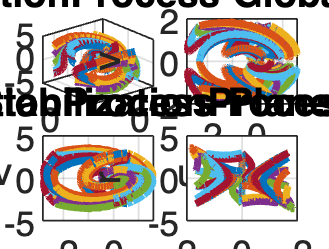


% u=10;   % [-15,15]   %军舰的航速 30 knot = 15.433 m/s
% v=0;    % [-6,6]
% r=0;    % [-2,2]     %状态变量
% Wu=0;   % [0,1200]
% Wv=0;   % [-9000,0]
% Wr=0;   % [-1200,0] 
% taou=0; % [-1.0e+6,1.0e+6];
% taor=0; % [-1.0e+6,1.0e+6];
% shipfcn(8,3,1,600,-4500,-600,1e+6,0)

theta=(0:2:10)*pi/10;
phi=(0:4:20)*pi/10;
rou=3;
x0=rou.*sin(theta).*cos(phi);
y0=rou.*sin(theta).*sin(phi);
z0=rou.*cos(theta);
ltt=length(theta);

figure('color','w')
subplot(221)
for i=1:ltt
    for j=1:ltt
        for k=1:ltt
            [t,y] = ode45(@shipfcn,[-15,15],[x0(i);y0(j);z0(k)]);
%             plot3(y(:,1),y(:,2),y(:,3),'linewidth',0.5);
            quiver3(y(:,1),y(:,2),y(:,3),gradient(y(:,1)),gradient(y(:,2)),gradient(y(:,3)),'linewidth',2);%增加轨迹方向箭头
            hold on
        end
    end
end
xlabel('u');ylabel('v');zlabel('r');
title('StabilizationProcess-Global');
box on;axis on;
view(-40,30);

subplot(222)
for i=1:ltt
    for j=1:ltt
        for k=1:ltt
            [t,y] = ode45(@shipfcn,[-15,15],[x0(i);y0(j);z0(k)]);
%             plot3(y(:,1),y(:,2),y(:,3),'linewidth',0.5);
            quiver3(y(:,1),y(:,2),y(:,3),gradient(y(:,1)),gradient(y(:,2)),gradient(y(:,3)),'linewidth',2);%增加轨迹方向箭头
            hold on
        end
    end
end
xlabel('u');ylabel('v');zlabel('r');
title('StabilizationProcess-Plane_uv');
box on;axis on;
view(0,90); 
% view(0,0); 
% view(-90,0);

subplot(223)
for i=1:ltt
    for j=1:ltt
        for k=1:ltt
            [t,y] = ode45(@shipfcn,[-15,15],[x0(i);y0(j);z0(k)]);
%             plot3(y(:,1),y(:,2),y(:,3),'linewidth',0.5);
            quiver3(y(:,1),y(:,2),y(:,3),gradient(y(:,1)),gradient(y(:,2)),gradient(y(:,3)),'linewidth',2);%增加轨迹方向箭头
            hold on
        end
    end
end
xlabel('u');ylabel('v');zlabel('r');
title('StabilizationProcess-Plane_ur');
box on;axis on;
view(0,0);

subplot(224)
for i=1:ltt
    for j=1:ltt
        for k=1:ltt
            [t,y] = ode45(@shipfcn,[-15,15],[x0(i);y0(j);z0(k)]);
%             plot3(y(:,1),y(:,2),y(:,3),'linewidth',0.5);
            quiver3(y(:,1),y(:,2),y(:,3),gradient(y(:,1)),gradient(y(:,2)),gradient(y(:,3)),'linewidth',2);%增加轨迹方向箭头
            hold on
        end
    end
end
xlabel('u');ylabel('v');zlabel('r');
title('StabilizationProcess-Plane_vr');
box on;axis on;
view(-90,0);

function uvrdot = shipfcn (~,x) 
% u=x(1);
% v=x(2);
% r=x(3);
% Wu=x(4);
% Wv=x(5);
% Wr=x(6);
% taou=x(7);
% taor=x(8);

m=23.8000;
Iz=1.7600;
err_model=0;
Xu=-0.7225*(1+err_model);
Yv=-0.8612*(1+err_model);
Nr=-1.90*(1+err_model);
Xdu=-2.0*(1+err_model);
Ydv=-10.0*(1+err_model);
Ndr=-1.0*(1+err_model);
Xuu=-1.3274*(1+err_model);
Yvv=-36.2823*(1+err_model);
Nrr=-0.75*(1+err_model);
m11=m-Xdu;
m22=m-Ydv;
m33=Iz-Ndr;
% d11=-(Xu+Xuu*abs(u)); 
% d22=-(Yv+Yvv*abs(v)); 
% d33=-(Nr+Nrr*abs(r));
% u_dot=(tau+Wu-d11*u+m22*v*r)/m11;
% v_dot=(Wv-d22*v-m11*u*r)/m22;
% r_dot=(delta+Wr-d33*r+(m11-m22)*u*v)/m33;

uvrdot=[((Xu+Xuu*abs(x(1)))*x(1)+m22*x(2)*x(3))/m11;((Yv+Yvv*abs(x(2)))*x(2)-m11*x(1)*x(3))/m22;((Nr+Nrr*abs(x(3)))*x(3)+(m11-m22)*x(1)*x(2))/m33];
% uvrdot=[(x(7)+X(4)+(Xu+Xuu*abs(x(1)))*x(1)+m22*x(2)*x(3))/m11;(X(5)+(Yv+Yvv*abs(x(2)))*x(2)-m11*x(1)*x(3))/m22;(x(6)+x(8)+(Nr+Nrr*abs(x(3)))*x(3)+(m11-m22)*x(1)*x(2))/m33];
% uvrdot=[(taou+Wu-d11*u+m22*v*r)/m11;(Wv-d22*v-m11*u*r)/m22;(taor+Wr-d33*r+(m11-m22)*u*v)/m33];
end
